# Deep Learning mit MATLAB

clear
clc
rng(1, "twister")

% Die MATLAB Deep LEarning Toolbox stellt einige Funktionen zum Arbeiten mit Tiefen NEuronalen Netzen zur Verfügung.
% Stellen Sie sicher, das der Arbeitspfad richtig eingestellt ist, da sonst
% die Bilder nicht gefunden werden kann. 

filename = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt";
cd(filename)


## Daten Laden und Data Store erstellen

filename = filename + "\09_Trainingsdaten\AusgeschnittenFürTraining\99_Trainingsdatensätze\01_3Kat30_ohne_30empfehlung";
imdsSchilder = imageDatastore(filename, "IncludeSubfolders", true, "LabelSource", "foldernames");

## Explorative Datenanalyse

% numImgs = length(imdsZahlen.Files)
countEachLabel(imdsSchilder)

ans = 3×2 table
                Label                Count
    _____________________________    _____

    BilderOhneSchilder                408 
    Geschwindigkeitsbegrenzung_30     402 
    Geschwindigkeitsempfehlung_30     591 


%genau gleiche viele einträge von jedem Label
numPerLabel =min(countEachLabel(imdsSchilder).Count)

numPerLabel = 402

% Labels extrahieren
allLabels = unique(imdsSchilder.Labels);
balancedFiles = [];

for i = 1:numel(allLabels)
    label = allLabels(i);
    % Alle Bilder mit diesem Label holen
    idx = find(imdsSchilder.Labels == label);
    % Wenn mehr als numPerLabel vorhanden, zufällig auswählen
    if numel(idx) >= numPerLabel
        selectedIdx = randsample(idx, numPerLabel);
        balancedFiles = [balancedFiles; imdsSchilder.Files(selectedIdx)];
    else
        warning("Label '%s' hat weniger als %d Bilder.", label, numPerLabel);
    end
end

% Neuen ImageDatastore mit ausgewählten Dateien erstellen
balancedDS = imageDatastore(balancedFiles, 'Labels', categorical(cellstr(extractBetween(balancedFiles, ...
    fullfile(filename, '\'), filesep))));

% img = read(imdsZahlen);
% figure;
% imshow(img)
% img = readimage(imdsZahlen, 1650);
% figure;
% imshow(img)
% size(img)


## Erzeuge Trainings- und Validierungsdatensatz

[imdsTrain, imdsValidation] = splitEachLabel(balancedDS, 0.8, "randomized");
%für trainnet müssen die Labels seperat vorliegen
% Wandle Labels in kategorisches Format um (falls nicht schon so)
cleanLabels = categorical(imdsTrain.Labels);
labelsTrain = arrayDatastore(cleanLabels, 'OutputType', 'same');
% filename = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\06_python\Quantisierungsbilder";
%labels ansehen
%allLabels = readall(labelsTrain);
%disp(allLabels)
%Quanti Datensatz
% imdsSchilder2 = imageDatastore(filename, "IncludeSubfolders", true, "LabelSource", "foldernames");

## Defeniere Netzwerkschichten

% Einfaches CNN definieren

layers = [
    imageInputLayer([48, 48, 3], "Name", "input", "Normalization", "none")
    convolution2dLayer(3, 8, 'Padding', 'same', "Name", "conv_1")
    reluLayer("Name", "relu_1")
    maxPooling2dLayer(2, 'Stride', 2,"Name", "maxpool_1")
    convolution2dLayer(3, 16, 'Padding', 'same',"Name", "conv_2")
    reluLayer("Name", "relu_2")
    maxPooling2dLayer(2, 'Stride', 2, "Name", "maxpool_2")
    convolution2dLayer(1, 3, "Name", "conv_3")
    globalAveragePooling2dLayer("Name", "gap")
    % fullyConnectedLayer(2, "Name", "fc") 
    softmaxLayer("Name", "softmax")
];



## Exploration des Netzwerkes

% layers(1).Name
% layers(1). InputSize
% layers(end-2).OutputSize

## Anpassen Hyperparameter

%sicherstellen das alle Bilder die gleiche größe haebn
augTrain  = augmentedImageDatastore([48 48 3], imdsTrain, ...
    'ColorPreprocessing', 'none', ...
    'OutputSizeMode', 'resize');
augVal = augmentedImageDatastore([48 48 3], imdsValidation, ...
    'ColorPreprocessing', 'none', ...
    'OutputSizeMode', 'resize');
aug2= augmentedImageDatastore([48 48 3], imdsSchilder, ...
    'ColorPreprocessing', 'none', ...
    'OutputSizeMode', 'resize');
% augQuanti= augmentedImageDatastore([48 48 3], imdsSchilder2, ...
%     'ColorPreprocessing', 'none', ...
%     'OutputSizeMode', 'resize');
% Trainingsparameter Schlake
% opts = trainingOptions("adam", "ValidationData", augVal, "Shuffle", "every-epoch", "Plots", "training-progress","InitialLearnRate",0.01);
% Schwellenwert definieren
lossThreshold = 0.02;

% Stop-Funktion als Function-Handle
stopFcn = @(info) stopIfLowLoss(info, lossThreshold);

% Trainingsparameter 

options = trainingOptions('adam', ...
 'MaxEpochs', 100, ...
 "InitialLearnRate", 0.0005, ...
    'MiniBatchSize', 16, ...
    'Shuffle', 'every-epoch', ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    ValidationData=augVal, ...
    ValidationFrequency=60, ...
    Verbose=false);

## Training

net = trainnet(augTrain, layers, "crossentropy", options);
netGAP = net;
save("netGAP.mat", "netGAP");

## Schätzung

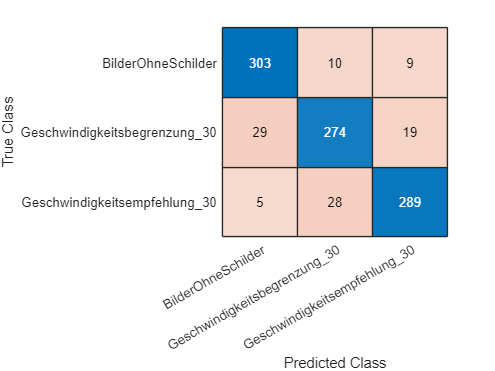


%Confumap Trainingsdatensatz
tbl = readall(augTrain);           % Liefert eine Tabelle mit Bildern
imgs = tbl{:,1};                 % Hole die Bilder aus der ersten Spalte als Cell-Array
TTrain = imdsTrain.Labels;
classNames = categories(TTrain);

XTrain = cat(4,imgs{:});
XTrain = single(XTrain);

outputs  = minibatchpredict(net,XTrain);
YTrain = onehotdecode(squeeze(outputs)',classNames,2);
confusionchart(TTrain,YTrain)

confMat = confusionmat(imdsTrain.Labels, YTrain);
accuracy = sum(diag(confMat)) / sum(confMat(:));
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 89.65%


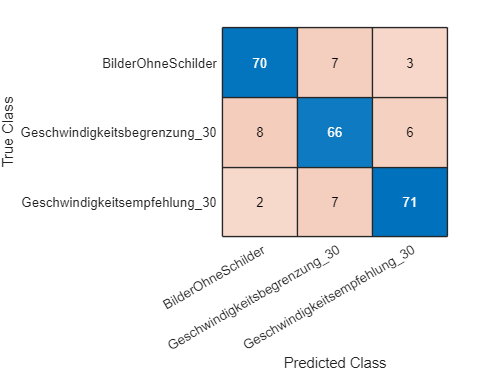


prob = squeeze(outputs); 

% 4) Scatterplot erstellen (mit Farbcode nach true Label)
% figure;
% gscatter(...
%     prob(1,:), ...                    % X-Werte: P(Klasse 1)
%     prob(2,:), ...                    % Y-Werte: P(Klasse 2)
%     TTrain, ...                       % Gruppierung nach echtem Label
%     'rb', ...                         % Farben: rot/blau
%     'o', ...                          % Marker: Kreis
%     8);                               % Markergröße
% 
% xlabel('P(Klasse 1)');
% ylabel('P(Klasse 2)');
% title('Scatter-Plot der Klassifikations-Wahrscheinlichkeiten');
% legend(categories(TTrain), 'Location', 'best');
% grid on;
% %axis square;

%Confumap Testdatensatz
tbl = readall(augVal);           % Liefert eine Tabelle mit Bildern
imgs = tbl{:,1};                 % Hole die Bilder aus der ersten Spalte als Cell-Array
TTest = imdsValidation.Labels;
classNames = categories(TTest);

XTest = cat(4,imgs{:});
XTest = single(XTest);

YTest = minibatchpredict(net,XTest);
YTest = onehotdecode(squeeze(YTest)',classNames,2);
confusionchart(TTest,YTest)

confMat = confusionmat(imdsValidation.Labels, YTest);
accuracy = sum(diag(confMat)) / sum(confMat(:));
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 86.25%


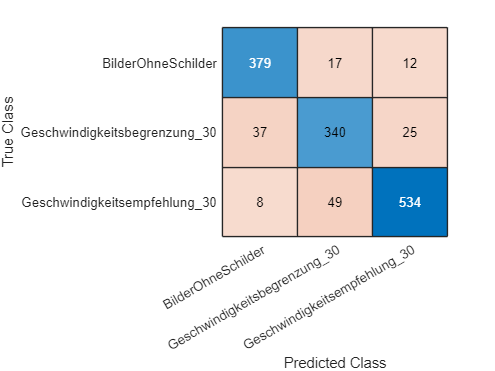


%Confumap Gesamtbestand
tbl = readall(aug2);           % Liefert eine Tabelle mit Bildern
imgs = tbl{:,1};                 % Hole die Bilder aus der ersten Spalte als Cell-Array
TTest2 = imdsSchilder.Labels;

XTest2 = cat(4,imgs{:});
XTest2 = single(XTest2);

YTest2 = minibatchpredict(net,XTest2);
YTest2 = onehotdecode(squeeze(YTest2)',classNames,2);

confusionchart(TTest2,YTest2)

confMat = confusionmat(imdsSchilder.Labels, YTest2);
accuracy = sum(diag(confMat)) / sum(confMat(:));
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 89.44%




% %Confumap Imdsschilder2
% tbl = readall(augQuanti);           % Liefert eine Tabelle mit Bildern
% imgs = tbl{:,1};                 % Hole die Bilder aus der ersten Spalte als Cell-Array
% TTest3 = imdsSchilder2.Labels;
% 
% XTest3 = cat(4,imgs{:});
% XTest3 = single(XTest3);
% 
% YTest3 = minibatchpredict(net,XTest3);
% YTest3 = onehotdecode(squeeze(YTest3)',classNames,2);
% 
% confusionchart(TTest3,YTest3)
% confMat = confusionmat(imdsSchilder2.Labels, YTest3);
% accuracy = sum(diag(confMat)) / sum(confMat(:));
% fprintf('Accuracy: %.2f%%\n', accuracy * 100);


## **Falsche Ergebnisse ausgeben**

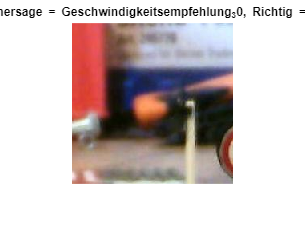

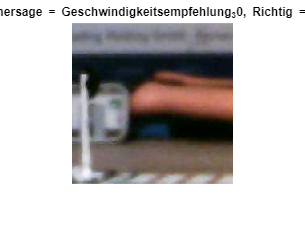

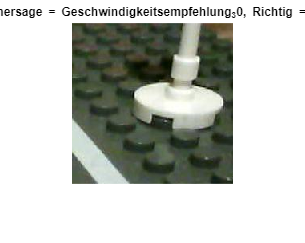

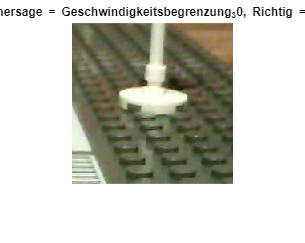

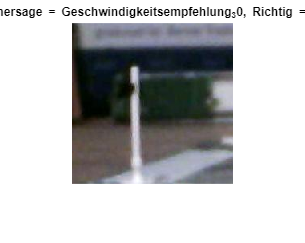

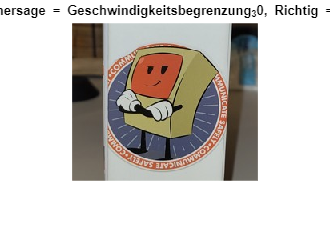

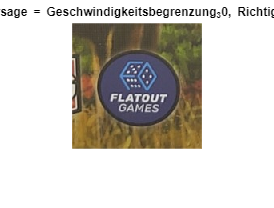

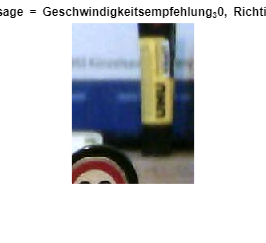

%Falsch erkantte Bilder anzeigen
trueLabelsTrain = imdsTrain.Labels;
trueLabelsVali = imdsValidation.Labels;
trueLabelsVali2 = imdsSchilder.Labels;

wrongIdxtrain = find(YTrain ~= trueLabelsTrain);
wrongIdxVali = find(YTest ~= trueLabelsVali);
wrongIdxVali2 = find(YTest2 ~= trueLabelsVali2);


for i = 1:length(wrongIdxtrain)
    img = readimage(imdsTrain, wrongIdxtrain(i));
    figure;
    imshow(img);
    title(sprintf("Falsch erkannt: Vorhersage = %s, Richtig = %s", ...
        string(YTrain(wrongIdxtrain(i))), string(trueLabelsTrain(wrongIdxtrain(i)))));
end


for i = 1:length(wrongIdxVali)
    img = readimage(imdsValidation, wrongIdxVali(i));
    figure;
    imshow(img);
    title(sprintf("Falsch erkannt: Vorhersage = %s, Richtig = %s", ...
        string(YTest(wrongIdxVali(i))), string(trueLabelsVali(wrongIdxVali(i)))));
end

dateiname = imdsSchilder.Files(wrongIdxVali2);
% for i = 1:length(wrongIdxVali2)
%     img = readimage(imdsSchilder, wrongIdxVali2(i));
%     figure;
%     imshow(img);
%     title(sprintf("Falsch erkannt: Vorhersage = %s, Richtig = %s", ...
%         string(YTest2(wrongIdxVali2(i))), string(trueLabelsVali2(wrongIdxVali2(i)))));
% end

## Evaluierung

filename = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\04_ModelleTrainieren";
cd(filename)
% exportNetworkToTensorFlow(net,"tf_model")
% save('meinNetz.mat', 'net');

